tau_list=logspace(-4,0,25)

tau_list =     0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0010    0.0015    0.0022    0.0032    0.0046    0.0068    0.0100    0.0147    0.0215    0.0316    0.0464    0.0681    0.1000    0.1468    0.2154    0.3162    0.4642    0.6813    1.0000


m_e_list=logspace(-3,1,25)

m_e_list =     0.0010    0.0015    0.0022    0.0032    0.0046    0.0068    0.0100    0.0147    0.0215    0.0316    0.0464    0.0681    0.1000    0.1468    0.2154    0.3162    0.4642    0.6813    1.0000    1.4678    2.1544    3.1623    4.6416    6.8129   10.0000


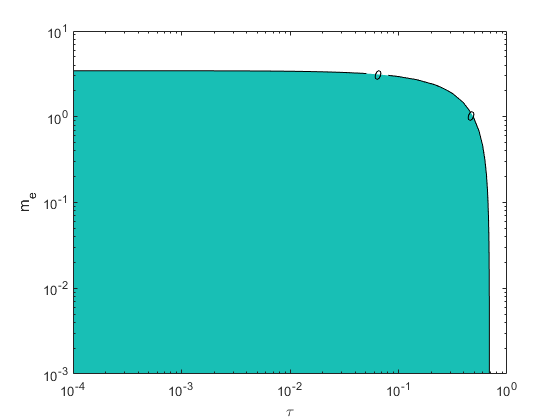

for i=1:length(tau_list)
    for j=1:length(tau_list)
        b_e=tau_list(i);
        m_e=m_e_list(j);
        plot_k_e(i,j)=eval(k_e_max);
        plot_m_e(i,j)=eval(m_e_min);
        plot_routh(i,j)=eval(eps1);
        plot_d_4(i,j)=eval(d_4);
        plot_d_6(i,j)=eval(d_6);
        plot_d_8(i,j)=eval(d_8);
    end
end
contourf(tau_list,m_e_list,plot_d_8,[0 0],'ShowText','on')
xlabel('\tau') 
ylabel('m_{e}') 
title('d_4')
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')


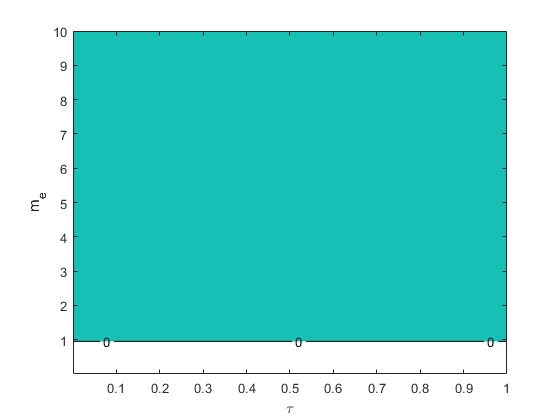

contourf(tau_list,m_e_list,plot_d_4,[0 0],'ShowText','on')
xlabel('\tau') 
ylabel('m_{e}') 

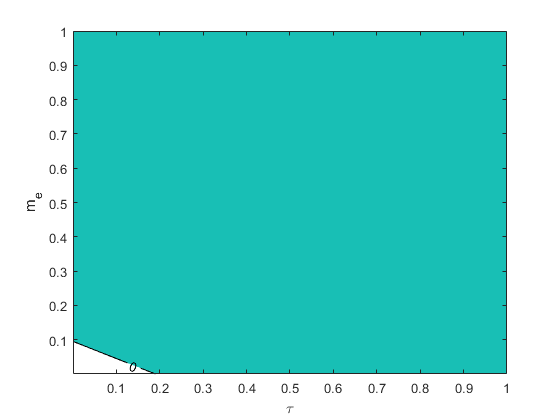


contourf(tau_list,tau_list,plot_d_6,[0 0],'ShowText','on')
xlabel('\tau') 
ylabel('m_{e}') 